# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF3_1_MachineLearning_Supervised

# Bond rating classification with ML 

One of the fundamental tasks in credit risk management is to **assign a credit grade to a borrower.** 

Grades are used to rank customers according to their perceived creditworthiness: better grades mean less risky customers; similar grades mean similar level of risk. 

** Credit ratings **are a small number of discrete classes, usually labeled with letters, such as 'AAA', 'BB-', etc. 

For corporate borrowers, one may consider certain financial ratios (e.g., sales divided by total assets), industry, etc. 

Here, we refer to these pieces of information about a borrower as *features* or *predictors*. 

Different institutions use different predictors, and they may also have different rating classes or score ranges to rank their customers. For relatively small loans offered to a large market of potential borrowers (e.g., credit cards), it is common to use credit scores, and the process of grading a borrower is usually automated. For larger loans, accessible to small- to medium-sized companies and larger corporations, credit ratings are usually used, and the grading process may involve a combination of automated algorithms and expert analysis.

# Workflow for ML using Credit Rating as example

Description of the data:

- Price : market price of the bond (numeric)

- Coupon : coupon rate of the bond (numeric)

- TM : yield to maturity of the bond (numeric)

- CurrentYield : current yield of the bond (numeric)

- Rating : credit rating of the bond (categorical: AAA, AA, A, BBB, BB, B, CCC, CC, D, NA, Not Rated)

We have selected for this simpliidied example only numeric features (Price, Coupon, YTM, Current Yield) and the Rating as classes.

## Import Existing Data

In this example, the data is loaded from the available spredsheet. One may make use of the interactive tools to load the data and auto-generate the code for the purpose of automation.


data = readtable('data_Bond.xlsx');


## Data Exploration

One may bring in data from a variety of sources. After that, it is possible to visualize the data, determine interesting patterns (if they exist), build intuition around the data, find outliers or missing information. Many of these typical tasks may be performed interactively.

## Convert Categorical Data into Nominal Arrays

Categorical data contains discret pieces of information, for instance, the credit rating in this dataset. One can open the variable in Variable Editor and convert categorical attributes into nominal arrays using the interactive tools. MATLAB will prompt you with the command in the Command Window.

data.Rating = categorical(data.Rating);





## Visualize Data

One can open the variable data, in the Variable Editor and interactive create different kinds of plots by selecting 1 or more columns.

As you create the plots, MATLAB tries to help by echoing the commands on to the Command Window.

Bond coupon vs. price, differentiated by  credit rating

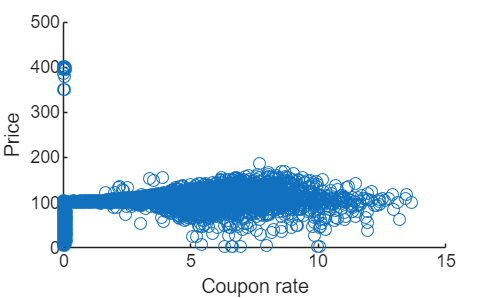

scatter(data.Coupon,data.Price)
xlabel('Coupon rate')
ylabel('Price')

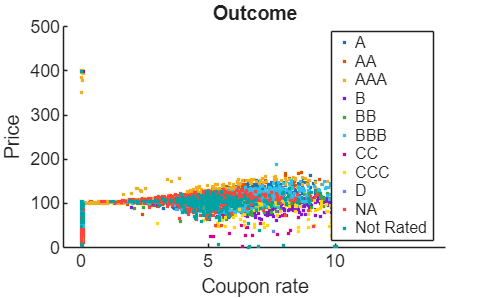

gscatter(data.Coupon,data.Price,data.Rating)
% Label the plot
xlabel('Coupon rate')
ylabel('Price')
title('Outcome')

You can visualize categories using an histogram

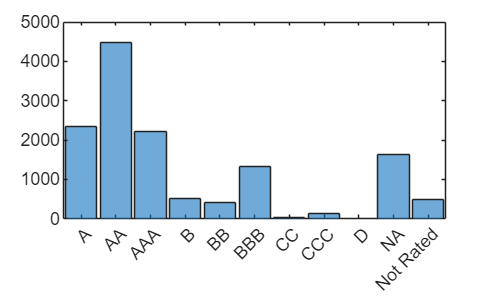


histogram((data.Rating))

A boxplot is a simple way to visualize multiple distributions.

`boxplot(x,c)`

creates a plot where the boxes represent the distribution of the values of `x` for each of the classes in `c`. If the values of `x` are typically significantly different for one class than another, then `x` is a feature that can distinguish between those classes. The more  features you have that can distinguish different classes, the more  likely you are to be able to build an accurate classification model from the full data set.

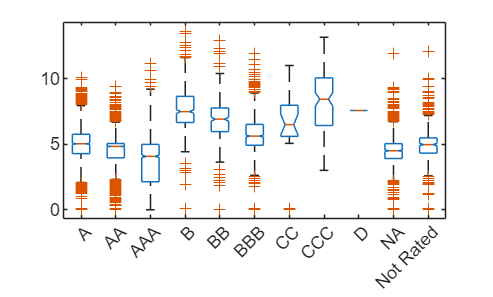


 boxplot(data.Coupon,data.Rating,'notch','on')

Box plots provide a visualization of summary statistics for sample data and contain the following features:

- The tops and bottoms of each “box” are the 25th and 75th percentiles of the samples, respectively. The distances between the tops and bottoms are the interquartile ranges (where 50% of your data fall). You can compute the value of the interquartile range using [`iqr`](https://uk.mathworks.com/help/stats/prob.normaldistribution.iqr.html).

- The line in the middle of each box is the sample median. If the median is not centered in the box, it shows sample skewness. You can compute the value of the median using the [`median`](https://uk.mathworks.com/help/matlab/ref/median.html) function.

- The whiskers are lines extending above and below each box. Whiskers are drawn from the ends of the interquartile ranges to the furthest observations within the whisker length (the *adjacent values*).

- Observations beyond the whisker length are marked as outliers. By default, an outlier is a value that is more than 1.5 times the interquartile range away from the top or bottom of the box, but this value can be adjusted with additional input arguments. Outliers are displayed with a red + sign.

- Notches display the variability of the median between samples. The width of a notch is computed so that box plots whose notches do not overlap have different medians at the 5% significance level. The significance level is based on a normal distribution assumption, but comparisons of medians are reasonably robust for other distributions. Comparing box-plot medians is like a visual hypothesis test, analogous to the *t* test used for means. Although not a formal test, if two boxes' notches  do not overlap there is ‘strong evidence’ (95% confidence) their medians differ. 

 Although notches is not a formal test, if two boxes' notches  do not overlap there is ‘strong evidence’ (95% confidence) their medians differ. 

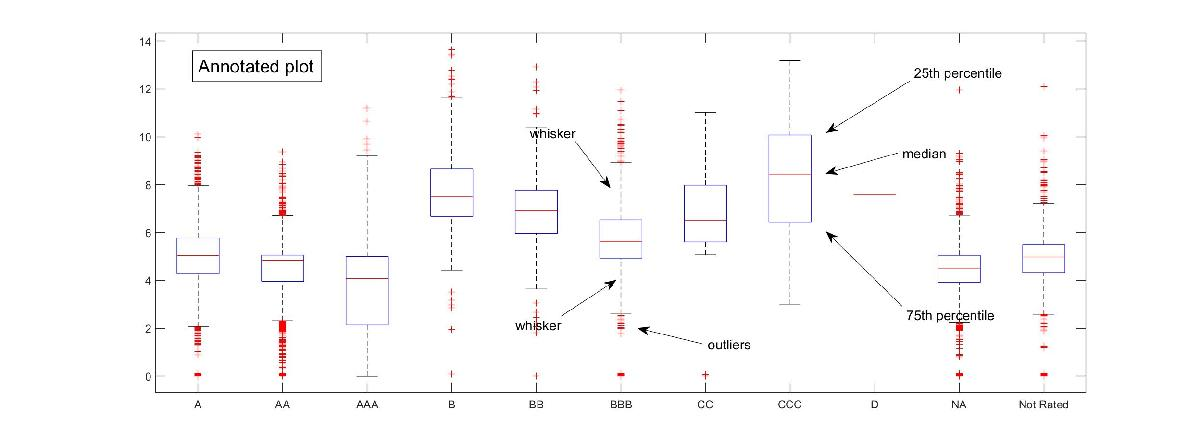

Because box plots show less detail than histograms, they are most useful for side-by-side comparisons of two distributions.

## Prepare the Data: Response and Predictors

We can segregate the data into response and predictors. This will make it easier to call subsequent functions which expect the data in this format.

 Prepare the response

Y = data.Rating;
disp('Bond Rating')

Bond Rating


tabulate(Y)

      Value    Count   Percent
          A     2351     17.32%
         AA     4495     33.12%
        AAA     2213     16.31%
          B      513      3.78%
         BB      404      2.98%
        BBB     1331      9.81%
         CC       21      0.15%
        CCC      125      0.92%
          D        1      0.01%
         NA     1636     12.06%
  Not Rated      480      3.54%


Prepare the predictors

X = table2array(data(:,1:end-1));

## Cross Validation

Cross validation is almost an inherent part of machine learning. Cross validation may be used to compare the performance of different predictive modeling techniques. In this example, we use holdout validation. Other techniques including k-fold and leave-one-out cross validation are also available.

In this example, we partition the data into training set and test set. 

The training set will be used to calibrate/train the model parameters. 

The trained model is then used to make a prediction on the test set. 

Predicted values will be compared with actual data to compute the confusion matrix. 

**Confusion matrix is one way to visualize the performance of a machine learning technique.**

You can choose the percentage of data to hold. In the following you will hold 40% of the data, selected randomly, for test phase, but you can change the percentage.


cv = cvpartition(length(X),'holdout',0.40);


Pick the training set

Xtrain = X(training(cv),:);
Ytrain = Y(training(cv),:);

Pick the test set

Xtest = X(test(cv),:);
Ytest = Y(test(cv),:);

disp('Training Set')

Training Set


tabulate(Ytrain)

      Value    Count   Percent
          A     1422     17.46%
         AA     2700     33.16%
        AAA     1346     16.53%
          B      319      3.92%
         BB      244      3.00%
        BBB      741      9.10%
         CC       13      0.16%
        CCC       75      0.92%
          D        0      0.00%
         NA      996     12.23%
  Not Rated      286      3.51%


disp('Test Set')

Test Set


tabulate(Ytest)

      Value    Count   Percent
          A      929     17.11%
         AA     1795     33.07%
        AAA      867     15.97%
          B      194      3.57%
         BB      160      2.95%
        BBB      590     10.87%
         CC        8      0.15%
        CCC       50      0.92%
          D        1      0.02%
         NA      640     11.79%
  Not Rated      194      3.57%


## Classification Using Nearest Neighbors

We saw that a  way to classify an observation is to use the same class as the nearest known examples. This is called a k-nearest neighbor (kNN) model. 

The basic idea here is that we don't just take the nearest neighbors, we take some number of nearest neighbors, usually an odd number, and we just let them vote.

One of the problems with K nearest neighbors is efficiency. If you're trying to define K nearest neighbors and K is bigger, it takes longer. So we worry about how big K should be. And if we make it too big-- and this is a crucial thing-- we end up getting dominated by the size of the class.

Various distance metrics such as euclidean, correlation, hamming, mahalonobis or your own distance metric may be used.

 Train the classifier

%data.Rating = nominal(data.Rating);


knn = ClassificationKNN.fit(Xtrain,Ytrain,'Distance','seuclidean');


 Make a prediction for the test set

Y_knn = knn.predict(Xtest);


#### Evaluating the performance of the algorithm

Compute the confusion matrix (or error matrix) of the true test labels YTest and the predicted labels, so to allow visualization of the performance of the algorithm. Using a confusion matrix makes it easy to see if the system is confusing two classes (i.e. commonly mislabeling one as another). 

For example, if I'm using 13 animals I can evaluate the performance of my algorithm with the following confusion matrix:

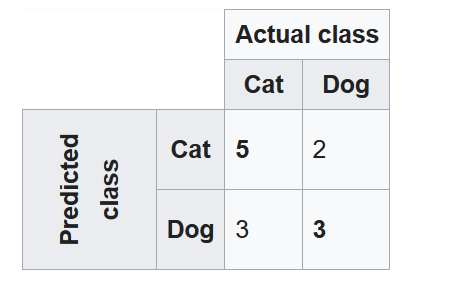

so that in general:

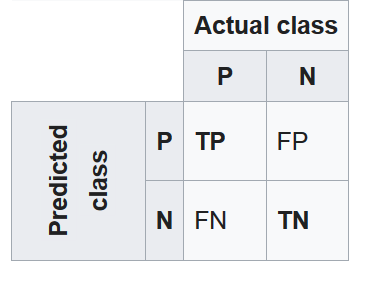

Let's get it for our algorithm applied in bond credit rating:

C_knn = confusionmat(Ytest,Y_knn);


Plot the confusion matrix 

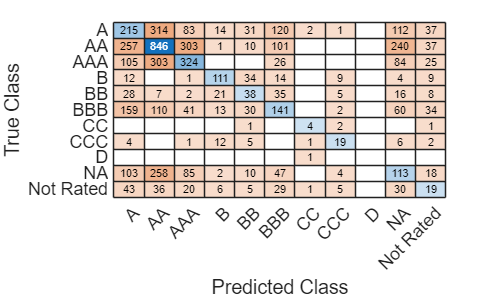



confusionchart(Ytest,Y_knn)

**The rows correspond to the predicted class (Output Class) and the  columns correspond to the true class (Target Class).**

 The diagonal cells  correspond to observations that are** correctly classified**. 

The  off-diagonal cells correspond to** incorrectly classified** observations.  Both the number of observations and the percentage of the total number  of observations are shown in each cell.

The column on the far  right of the plot shows the percentages of all the examples predicted to belong to each class that are correctly and incorrectly classified.  

These metrics are often called the precision (or positive predictive  value) and false discovery rate, respectively. The row at the bottom of  the plot shows the percentages of all the examples belonging to each  class that are correctly and incorrectly classified. These metrics are  often called the recall (or true positive rate) and false negative rate, respectively. The cell in the bottom right of the plot shows the  overall accuracy.

 Examine the confusion matrix for each class as a percentage of the true class

C_knn = bsxfun(@rdivide,C_knn,sum(C_knn,2)) * 100

C_knn =    23.1432   33.7998    8.9343    1.5070    3.3369   12.9171    0.2153    0.1076         0   12.0560    3.9828
   14.3175   47.1309   16.8802    0.0557    0.5571    5.6267         0         0         0   13.3705    2.0613
   12.1107   34.9481   37.3702         0         0    2.9988         0         0         0    9.6886    2.8835
    6.1856         0    0.5155   57.2165   17.5258    7.2165         0    4.6392         0    2.0619    4.6392
   17.5000    4.3750    1.2500   13.1250   23.7500   21.8750         0    3.1250         0   10.0000    5.0000
   26.9492   18.6441    6.9492    2.2034    5.0847   23.8983         0    0.3390         0   10.1695    5.7627
         0         0         0         0   12.5000         0   50.0000   25.0000         0         0   12.5000
    8.0000         0    2.0000   24.0000   10.0000         0    2.0000   38.0000         0   12.0000    4.0000
         0         0         0         0         0         0  100.0000         0         0         0    

# Predictive modelling

Having built a model from the data, you can use it to classify new  observations. 

This just requires calculating the features of the new  observations and determining which region of the predictor space they  are in.

The `predict` function determines the predicted class of new observations.

The inputs are the trained model and a table of observations, with the same predictor variables as were used to train the model. The output is a  categorical array of the predicted class for each observation in `newdata`.

`predClass = predict(model,newdata)`

The inputs are the trained model and a table of observations, with the same predictor variables as were used to train the model. The output is a  categorical array of the predicted class for each observation in `newdata`.

**Open the Classification Learner app.**

- Select `data` as the data to use.

- The app should correctly detect Rating as the response variable to predict.

- Choose the default validation option.

- Select a model and click the **Train** button.

Try a few of the standard models with default options. **See if you can achieve at least 80% accuracy**.

Note that SVMs work on binary classification problems (i.e. where there are  only two classes). To make SVMs work on this problem, the app is fitting many SVMs. These models will therefore be slow to train.

Similarly, ensemble methods work by fitting multiple models. These will also be slow to train.

[Book](https://books.google.it/books?id=bcRcDwAAQBAJ&pg=PA204&lpg=PA204&dq=classification+bond+matlab&source=bl&ots=667Bj9FUXf&sig=ACfU3U0rtnURqCGQXD6hN0ZJ-RcCZoWRIw&hl=it&sa=X&ved=2ahUKEwjQ5beF--_pAhXuTxUIHcd0AasQ6AEwAHoECAoQAQ#v=onepage&q=classification%20bond%20matlab&f=false)

Machine Learning: extracting information on the underlying process generating the data, directly from implicit patterns in the data.

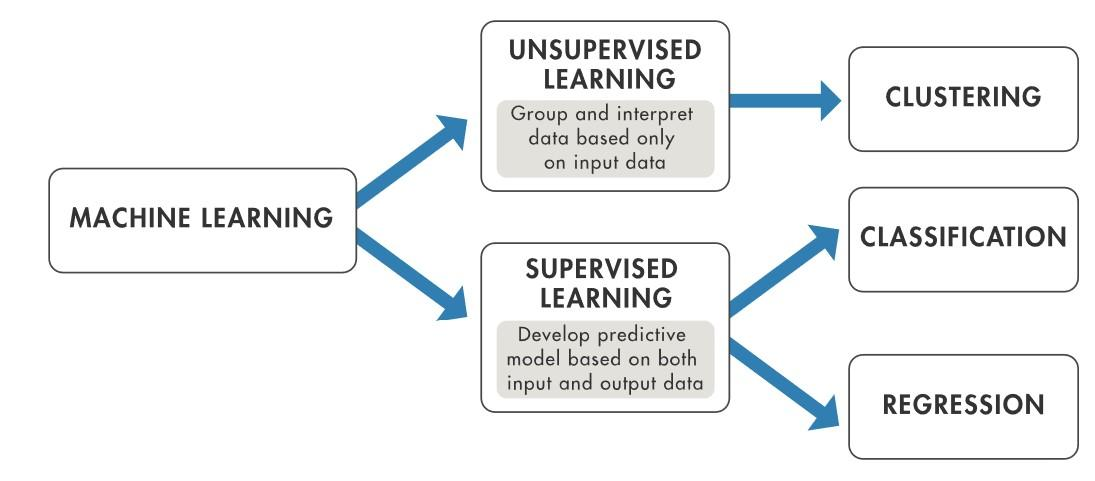

In predictive modelling you try to infer information about the process (model) that generated the data and use it to make predictions on new data.

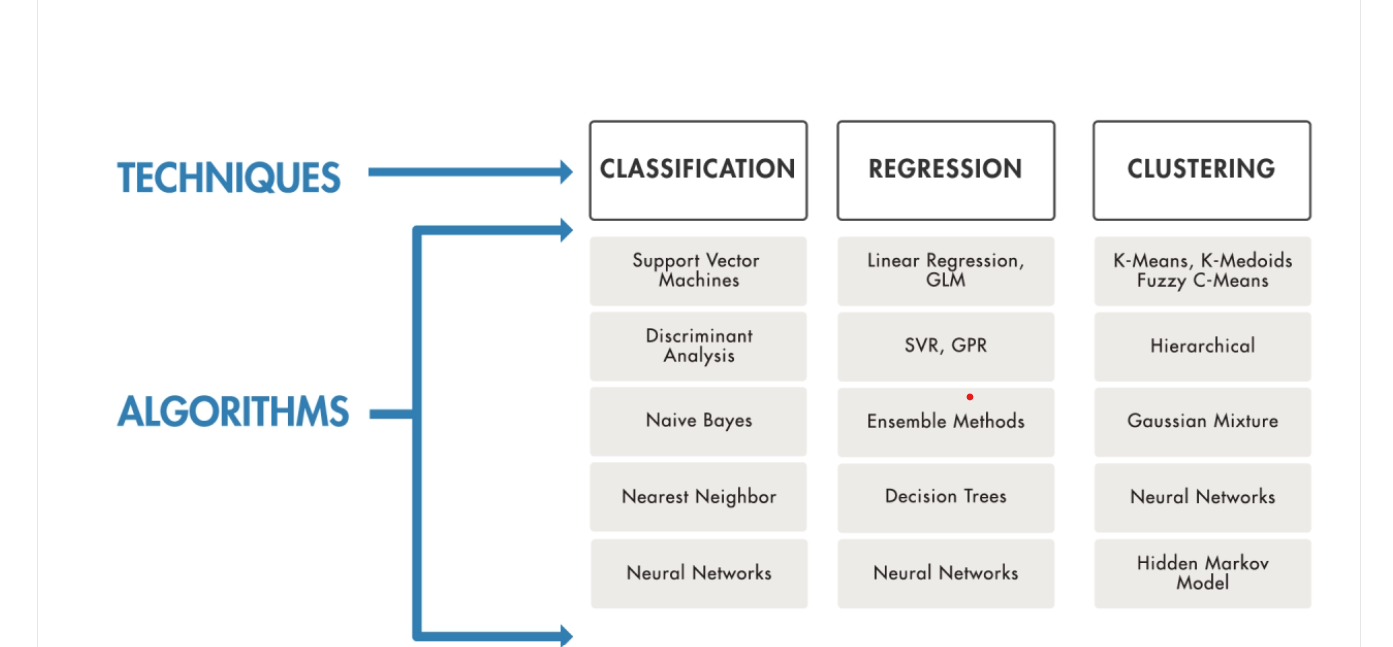

Machine learning is synonymous with n**on-parametric** modeling techniques. The term non-parametric is not meant to imply that such models completely lack parameters but that the number and nature of the parameters are flexible and determined from data.

Data with two **predictors **variables and two **output classes.**

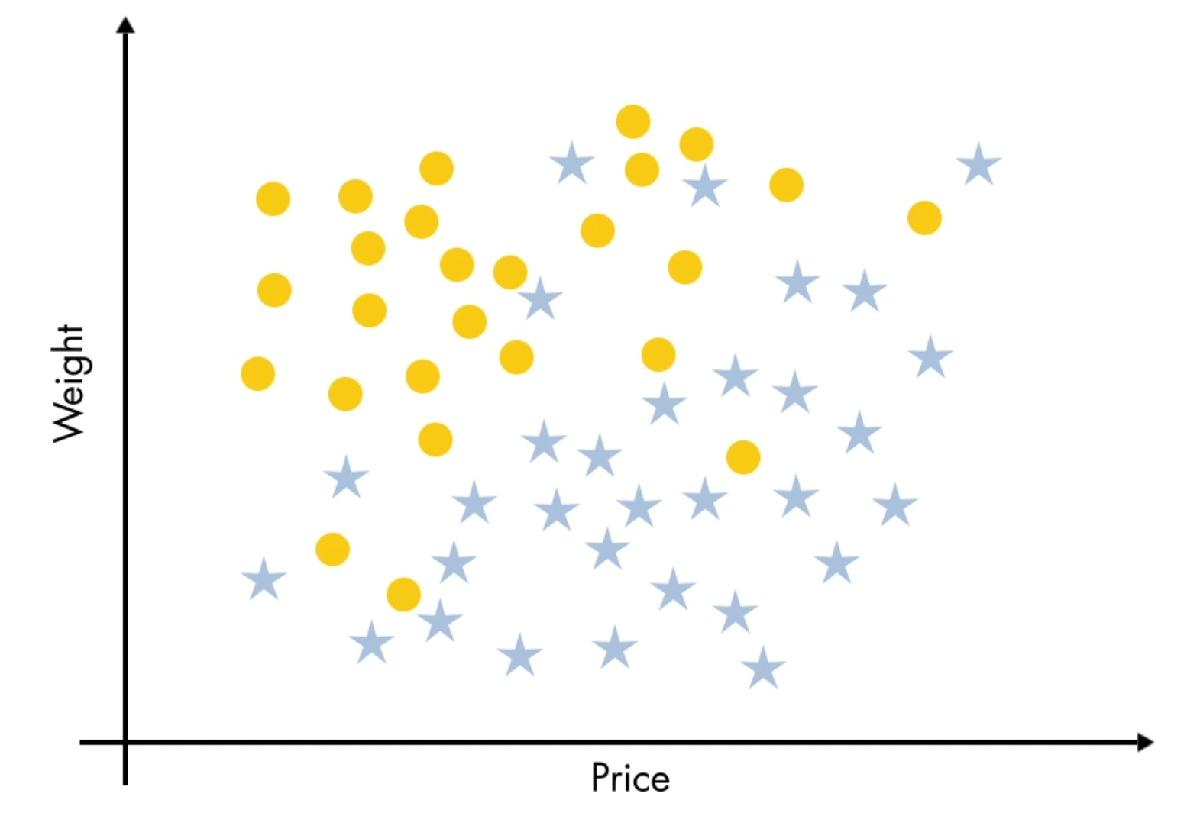

A** classification model** is just a division of the features space into regions.

Can you infer a classification model? Let's consider a **linear model**

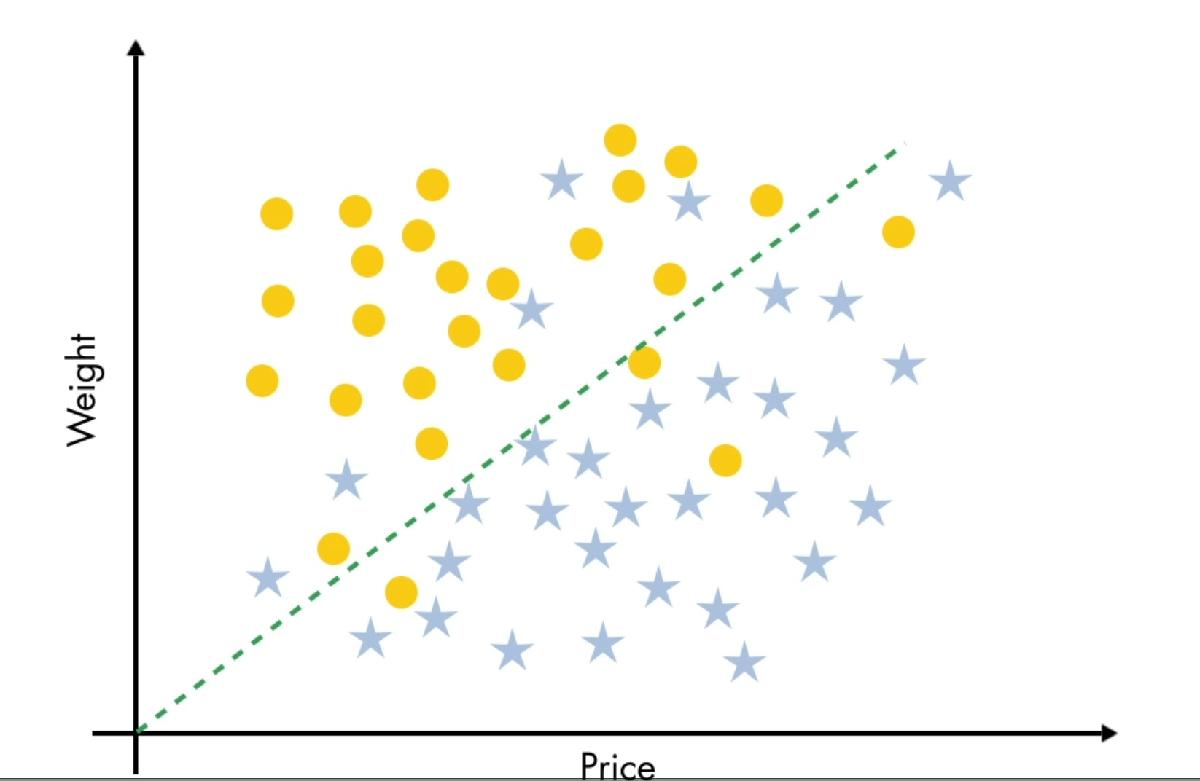

such that if price is greater than weight, than it is a star,otherwose a circle

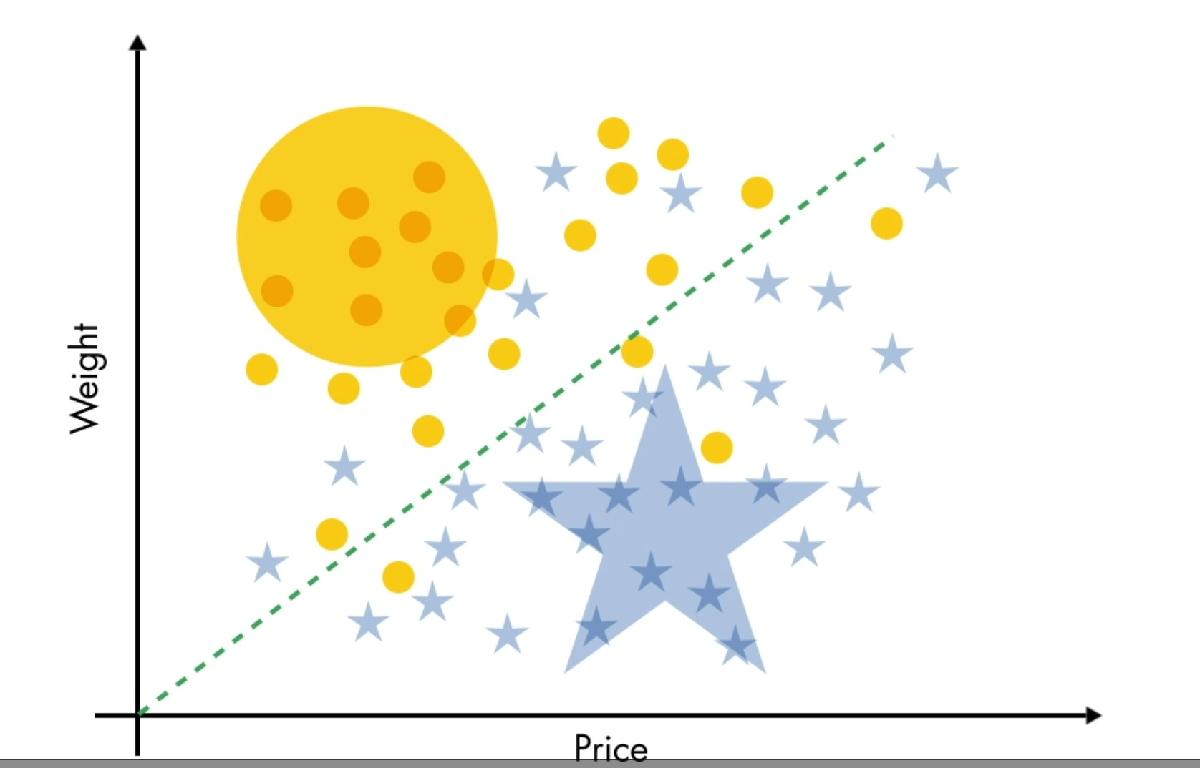

You might consider a much more complex model

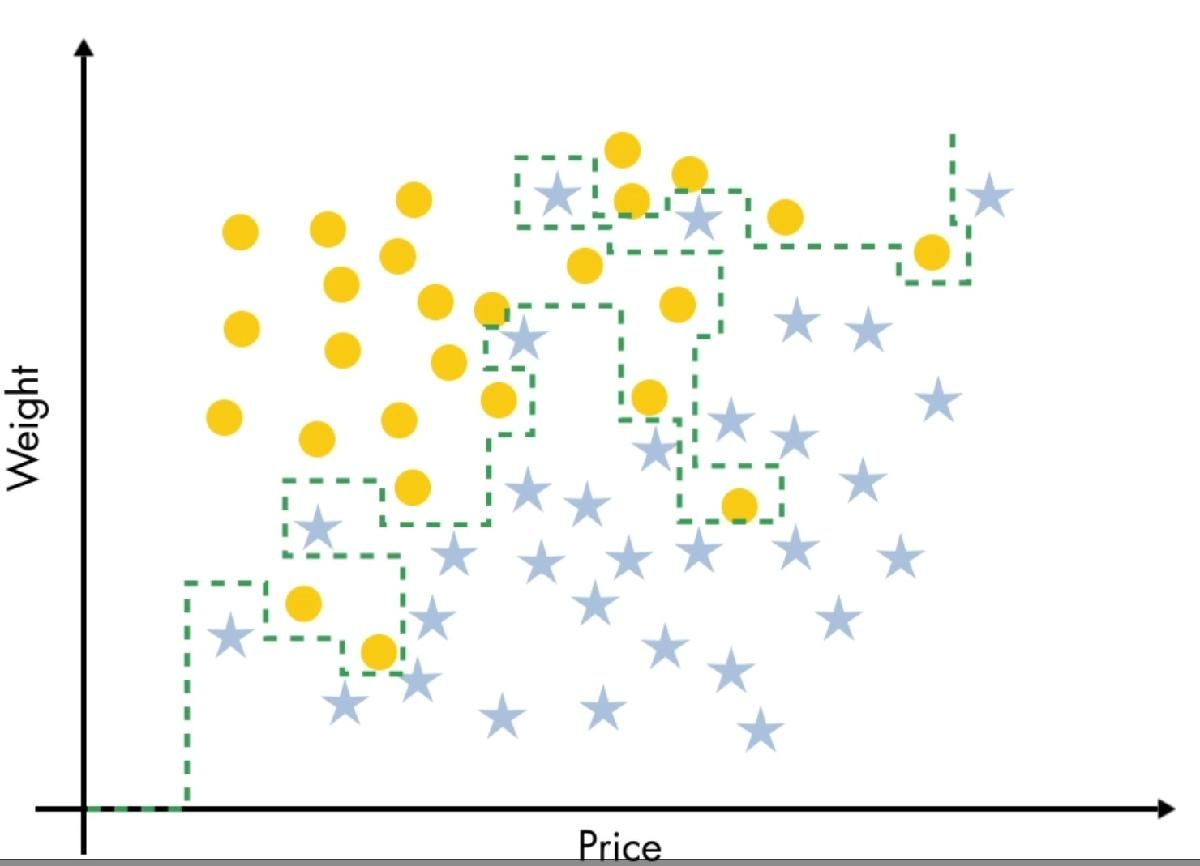

With respect ot accuracy, the second model is perfect, i.e. 100%.

But is easy to understand that probably that second model is capturing any detail of the data, even the** noise**.

Then try to use the models on **new data.**

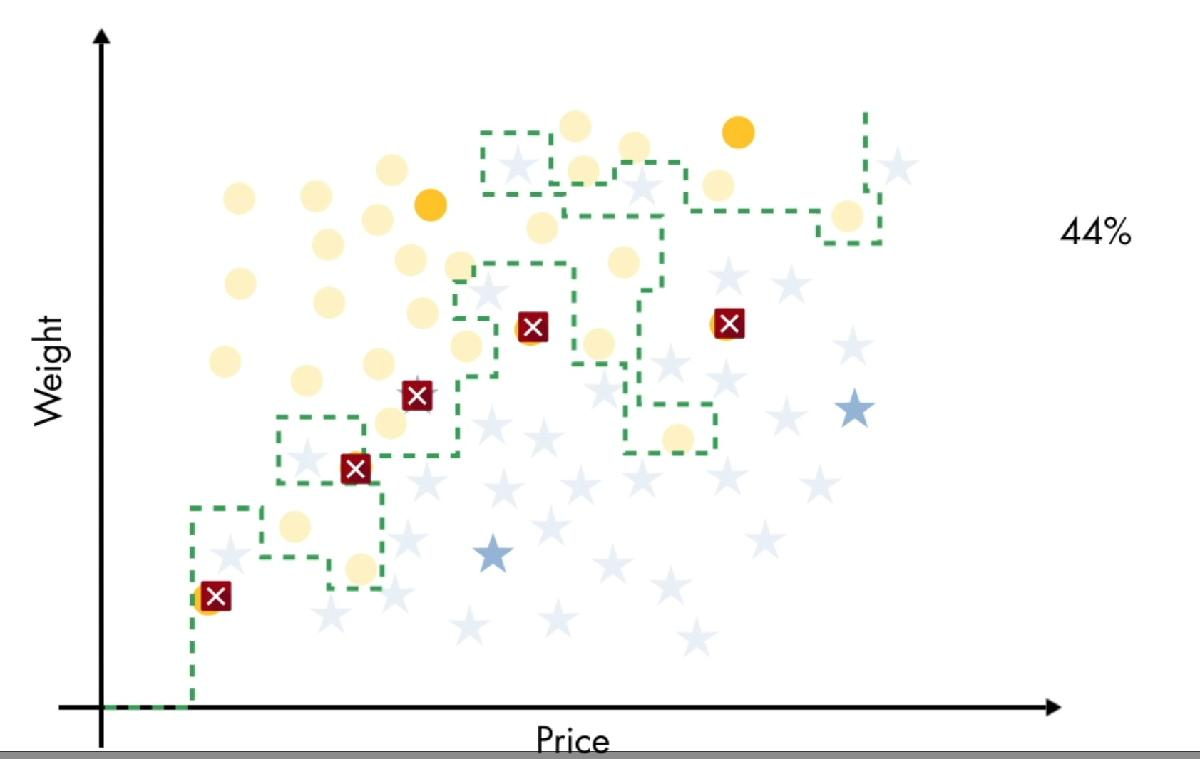

The model is said to be affected by Overfitting when if performs well on the training set but doesn't do as good on the test data.

Then you need to get test data from the given data, by dividing them into training and testing. Ususally you randomly pick some fraction of the observations that you put aside as test set.

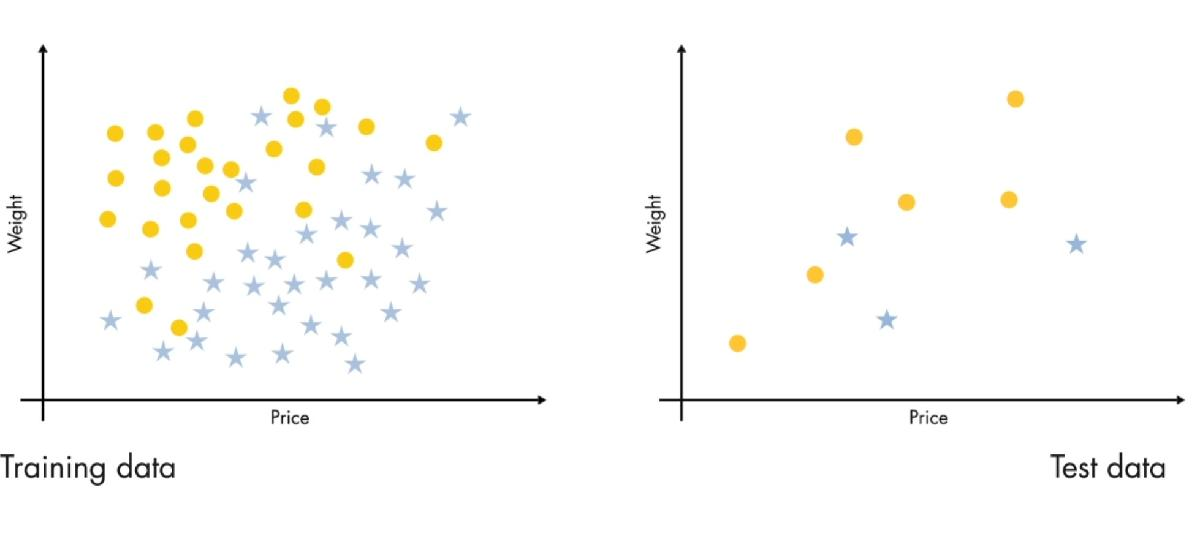

Here is the effect of testing an overfitted model:

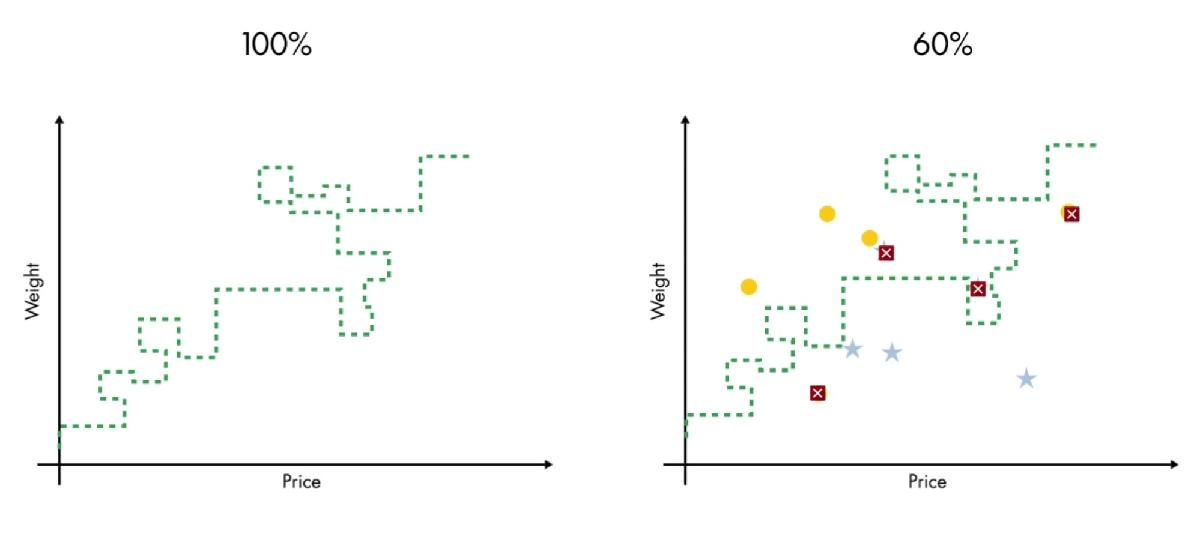

# Features

Choice of features matters. Throwing too many features in may, in fact, give us some overfitting. And in particular, deciding the weights that I want on those features has a real impact. And you, as a designer or a programmer, have a lot of influence in how you think about using those. So feature engineering really matters. How you pick the features, what you use is going to be important

# Sensitivity and specificity. 

Sensitivity basically tells you what percentage did I correctly find. And specificity said what percentage did I correctly reject. A trade-off comes in. I can make sensitivity 1.

Label everything is the thing I'm looking for.  Everything is correct. But the specificity will be 0. Because I'll have a bunch of things incorrectly labeled. I could make the specificity 1, reject everything. Say nothing as an instance. True negatives goes to 1, and I'm in a great place there, but my sensitivity goes to 0. I've got a trade-off. As I think about the machine learning algorithm I'm using and my choice of that classifier, I'm going to see a trade off where I can increase specificity at the cost of sensitivity or vice versa.

And you'll see a nice technique called ROC or Receiver Operator Curve that gives you a sense of how you want to deal with that.

How to choose the right k?

We take our training data and we split it into two parts. So we have training and testing, but now we just take the training, and we split that into training and testing multiple times. And we experiment with different K's, and we see which K's gives us the best result on the training data. And then that becomes our K. And that's a very common method. It's called cross-validation, and it's-- for almost all of machine learning, the algorithms have parameters in this case, it's just one parameter, K.

And the way we typically choose the parameter values is by searching through the space using this cross-validation in the training data. 

# Cross-validation

In conclusion, you need a** validation **to see how the model fits on new data.

# k-nearest neighbors (kNN) 

The function kmeans partitions data into k mutually exclusive clusters and returns the index of the cluster to which it assigns each observation. kmeans treats each observation in your data as an object that has a location in space. The function finds a partition in which objects within each cluster are as close to each other as possible, and as far from objects in other clusters as possible. You can choose a distance metric.

Fordetails, see 'Distance'.

At any point in the features space find the 5 closest training points and see their class, 

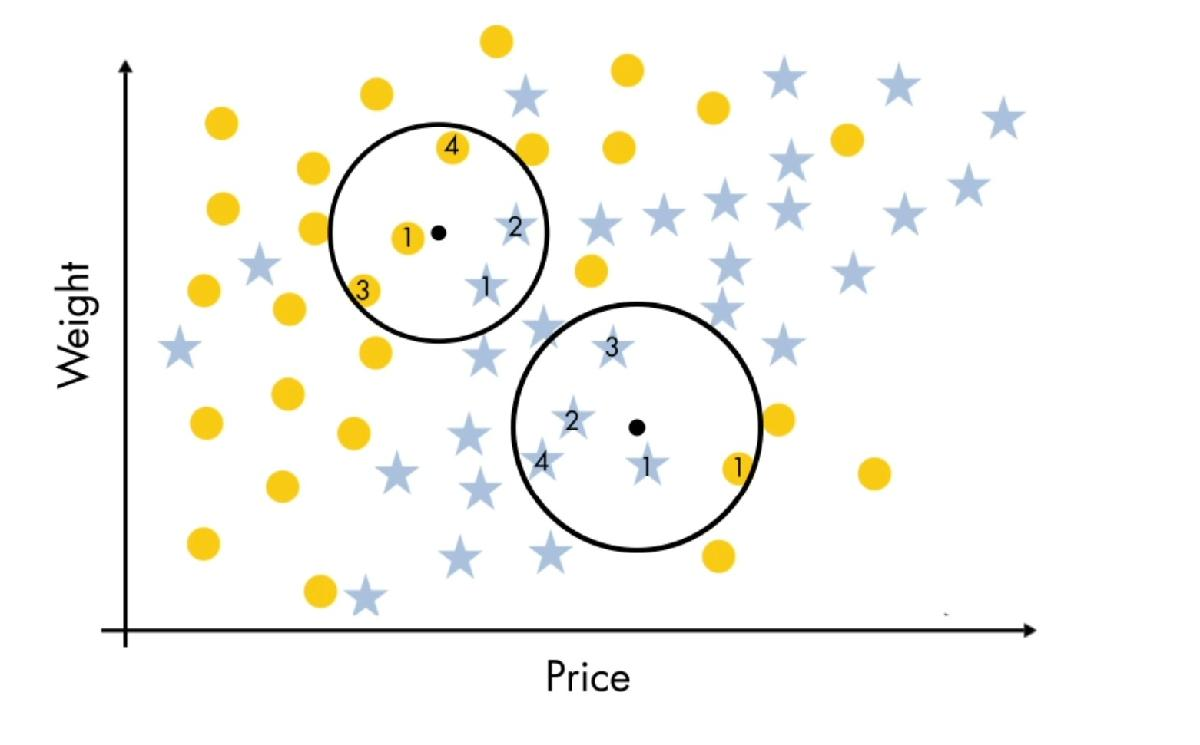

then use the most common class as the label for that space:

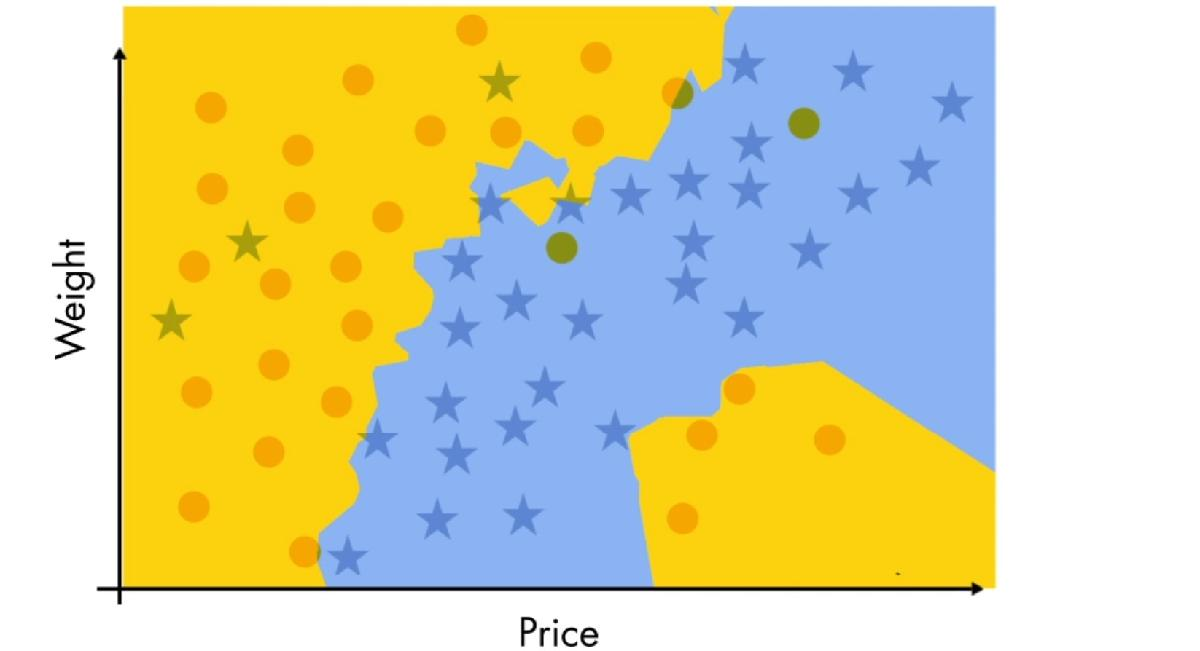

Then you can apply the same procedure to new data. The Machine (the procedure) learns (Learning) form the data.

There are many different procedures